# Analysis of Covid-19 WHO data

opts = weboptions;
opts.ContentType = 'table';
by_date = webread("https://opendata.ecdc.europa.eu/covid19/casedistribution/csv",opts);
by_date.Properties.VariableNames = ["date", "day", "month", "year", "cases", "deaths", "location", "geo_id", "code", "population"];

Preview 10 random rows

by_date(randi(height(by_date),1,10), :)

ans = 10×10 table
       date       day    month    year    cases    deaths       location        geo_id     code      population
    __________    ___    _____    ____    _____    ______    _______________    ______    _______    __________

    21/02/2020    21       2      2020       0        0      {'Italy'      }    {'IT'}    {'ITA'}    6.0431e+07
    02/02/2020     2       2      2020       0        0      {'Iran'       }    {'IR'}    {'IRN'}      8.18e+07
    21/03/2020    21       3      2020     534       30      {'Netherlands'}    {'NL'}    {'NLD'}    1.7231e+07
    09/02/2020     9       2      2020       0        0      {'Oman'       }    {

latestDate = max(by_date.date)

latestDate = datetime
   01/04/2020


## Group by country 

[G,ID] = findgroups( by_date.location);
ID = categorical(ID);
by_country = table;
by_country.name = ID;
by_country.geo_id = splitapply( @unique, by_date.geo_id, G );

### Calculate Totals

for n = 1:numel(ID)
    ix = find(G == n);
    by_date{ix,'total_deaths'}  = cumsum( by_date{ix,'deaths'}, 'reverse' );    
    by_date{ix,'total_cases'}   = cumsum( by_date{ix,'cases'}, 'reverse' );    
end

by_country.total_deaths = splitapply( @max, by_date.total_deaths, G );
by_country.total_cases = splitapply( @max, by_date.total_cases, G );

### Find date of Nth death

N = 50;
by_country.date_deaths_N = splitapply( @(t,dt) findExeedanceDate(t,dt,N), by_date.date, by_date.total_deaths , G );

### Summary Statistics

maxDeaths = max(by_country.total_deaths);
maxCases = max(by_country.total_cases);
by_country = sortrows(by_country,'total_deaths','descend');

#### 10 Worse Impacted Countries by Total Deaths

by_country(1:10,:)

ans = 10×5 table
              name              geo_id    total_deaths    total_cases    date_deaths_N
    ________________________    ______    ____________    ___________    _____________

    Italy                       {'IT'}       12430        1.0579e+05      03-Mar-2020 
    Spain                       {'ES'}        8189             94417      13-Mar-2020 
    United_States_of_America    {'US'}        4079        1.8962e+05      15-Mar-2020 
    France                      {'FR'}        3523             52128      13-Mar-2020 
    China                       {'CN'}        3310             82295      26-Jan-2020 
    Iran                        {'IR'}        2898             44606      02-Mar-2020 
    United_Kingdom              {'UK'}        1789             25150      17-Mar-2020 
    Netherlands              

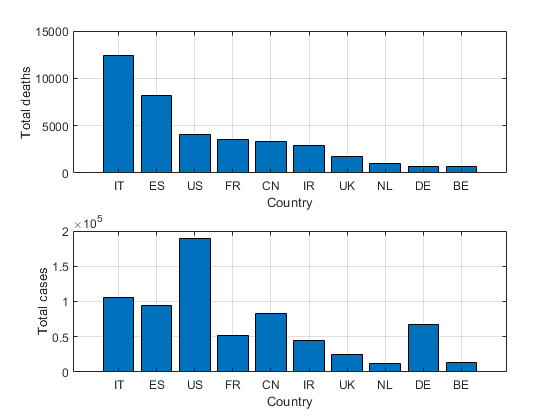

figure;
ax = subplot(2,1,1);
bar(ax,by_country{1:10,"total_deaths"})
ax.XTickLabel = by_country{1:10,"geo_id"};
xlabel('Country'); ylabel('Total deaths'); grid on;
ax = subplot(2,1,2);
bar(ax,by_country{1:10,"total_cases"})
ax.XTickLabel = by_country{1:10,"geo_id"};
xlabel('Country'); ylabel('Total cases'); grid on;

### Select countries to highlight

highlight = {'China' 'Italy' 'United_States_of_America' 'United_Kingdom' 'Spain'}

highlight = 1×5 cell array
    {'China'}    {'Italy'}    {'United_States_of_America'}    {'United_Kingdom'}    {'Spain'}


### Plot Total Death Count by Date

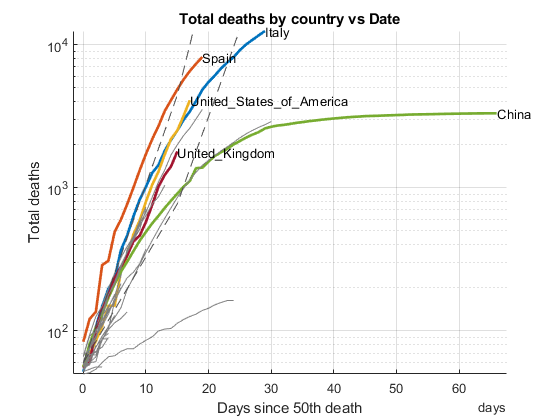

fig1 = figure;
ax1 = axes("NextPlot","add","YScale","log");
grid on
xlabel(ax1,"Days since " + num2str(N) + "th death")
ylabel(ax1,'Total deaths')
title( "Total deaths by country vs Date" )

for id = by_country.name'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N;
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    
    % Plot rate of deaths
    y = total_deaths;
    if any(id == highlight)
        semilogy(ax1, dt, y, 'LineWidth', 2)
        text(ax1, max(dt), max(y), strrep(char(id), '_', '\_'))
    else
        semilogy(ax1, dt, y, 'Color', [0.5 0.5 0.5])
    end
end
% Get time base
X = ax1.XTick;
xtickformat(ax1,'d')

ax1.YLimMode = 'manual';
c = [0.3 0.3 0.3];

% Apply 33% growth line
Y = 10*(1.33).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

% Apply 50% growth line
Y = 10*(1.50).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

### Plot Death Rate as Moving Average

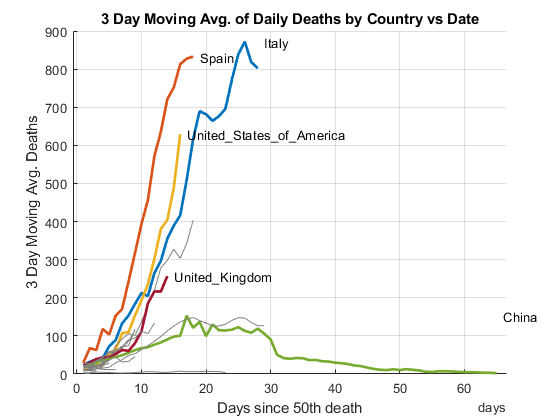

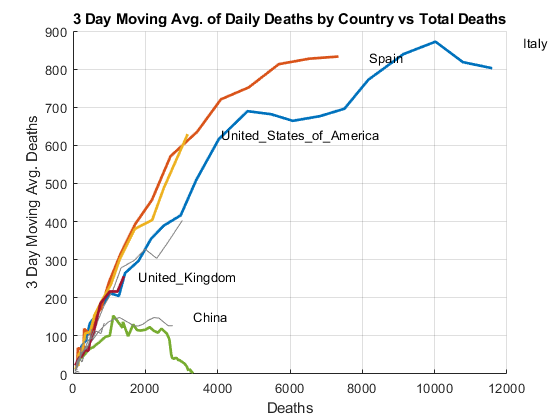

fig2 = figure;
ax2 = axes("NextPlot","add");
grid on
xlabel(ax2,"Days since " + num2str(N) + "th death")
ylabel(ax2,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Date" )

fig3 = figure;
ax3 = axes("NextPlot","add");
grid on
xlabel(ax3,"Deaths")
ylabel(ax3,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Total Deaths" )

for id = by_country.name'
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N;
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    mov_avg_deaths = movmean( by_date{ix,'deaths'}, 3, 'Endpoints', 'fill' );
    
    % Plot moving average
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax2, dt, y, 'LineWidth', 2)
        text(ax2, max(dt), max(y), strrep(char(id), '_', '\_'))
        xtickformat(ax2,'d')
    else
        plot(ax2, dt, y, 'Color', [0.5 0.5 0.5])
    end
    
    % Plot moving average vs deaths
    x = total_deaths;
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax3, x, y, 'LineWidth', 2)
        text(ax3, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax3, x, y, 'Color', [0.5 0.5 0.5])
    end
end

### UK Specific Data

country = by_country(by_country.name == "United_Kingdom",:);
disp(country)

         name         geo_id    total_deaths    total_cases    date_deaths_N
    ______________    ______    ____________    ___________    _____________

    United_Kingdom    {'UK'}        1789           25150        17-Mar-2020 



daily = by_date(by_date.location == "United_Kingdom",:);
ix = daily.date >= country.date_deaths_N;
daily = daily(ix,:);
latest_date = max(daily.date)

latest_date = datetime
   01/04/2020


delta_death_growth_ratio = daily.deaths ./ (daily.total_deaths - daily.deaths);
delta_case_growth_ratio = daily.cases ./ (daily.total_cases - daily.cases);


### Plot Daily Deaths & Cases

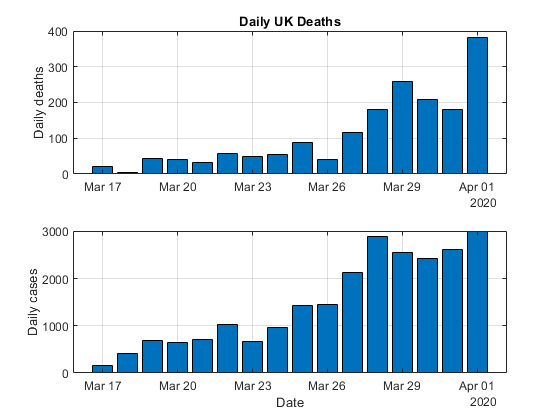

figure;
ax = subplot(2,1,1); bar( ax, daily.date, daily.deaths );
grid on;
ylabel('Daily deaths');
title("Daily UK Deaths")
ax = subplot(2,1,2); bar( ax, daily.date, daily.cases );
grid on;
ylabel('Daily cases');
xlabel('Date');

### Plot Daily Growth Rate

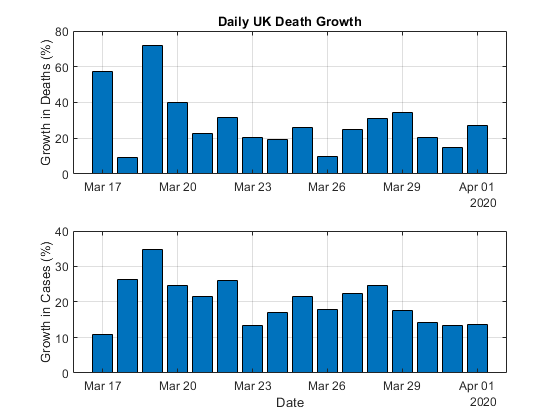

figure;
ax = subplot(2,1,1); bar( ax, daily.date, delta_death_growth_ratio * 100 );
grid on;
ylabel('Growth in Deaths (%)');
title("Daily UK Death Growth")
ax = subplot(2,1,2); bar( ax, daily.date, delta_case_growth_ratio * 100);
grid on;
ylabel('Growth in Cases (%)');
xlabel('Date');

### Plot Doubling Frequency

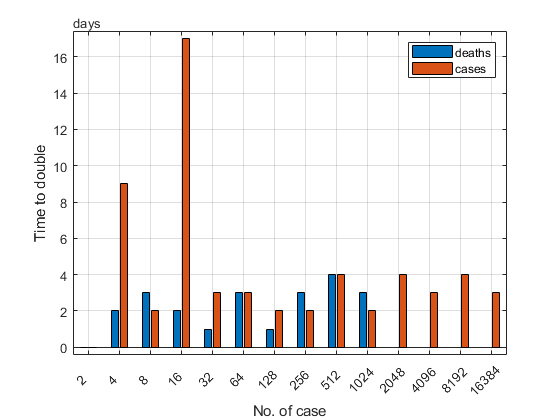

daily = by_date(by_date.location == "United_Kingdom",:);
daily = sortrows(daily,'date','ascend');

i = 1; n = 2;
freq_double = table;
while any(daily.total_cases > n)
    c = daily.date(find(daily.total_cases>=n,1));
    d = daily.date(find(daily.total_deaths>=n,1));
    if isempty(d); d = NaT; end
    freq_double(end+1,["i", "n","deaths","cases"]) = {i n d c};
    n = n * 2;
    i = i + 1;
end

freq_double.period_deaths = [days(0);days(diff(freq_double.deaths))];
freq_double.period_cases = [days(0);days(diff(freq_double.cases))];

figure
ax = axes;
bar(ax,[freq_double.i],[freq_double.period_deaths freq_double.period_cases]');

xlabel(ax,'No. of case')
ylabel(ax,'Time to double')
ax.XTickLabel = freq_double.n;
ax.XTickLabelRotation = 45;
legend(categorical(["deaths","cases"]))
grid on

function dt = findExeedanceDate( dates, value, threshold )
[dates,ix] = sort(dates,'ascend');
value = value(ix);

ix = value >= threshold;
if any(ix)
    dt = dates( find(ix,1) );
else
    dt = NaT;
end
end